# **R-factor: Calculate velocity changes **

## Introduction

**Authors**: Ivan Abakumov

**Publication date**: 28th of October 2019

**E-mail**: ivan.abakumov@fu-berlin.de

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load G-file and comsol data

% Model 7 - the last one
Results = MLD('/home/ivan/Desktop/Comsol/My_model_7_results.mat');
G = MLD('/home/ivan/Desktop/Comsol/My_model_7_G_file.mat');
Model = MLD('/home/ivan/Desktop/MLIB/Examples/R_factor/Data/Velmod_model_7');

% stress < 0 
% pressure > 0

tt = 101;

Bio = 0.3*ones(G.nx, G.nz);
Bio(1:301,286:316) = 0.95;

% sigma_xx = (Results.stress_x(:,:,tt) - SME(Bio,3).*Results.pressure(:,:,tt) ...
%          + Results.pressure(:,:,tt)) ...
%         - (Results.stress_x(:,:,1) - SME(Bio,3).*Results.pressure(:,:,1) ...
%          + Results.pressure(:,:,1)); 
% 
% sigma_zz = (Results.stress_y(:,:,tt) - SME(Bio,3).*Results.pressure(:,:,tt) ...
%          + Results.pressure(:,:,tt)) ...
%         - (Results.stress_y(:,:,1) - SME(Bio,3).*Results.pressure(:,:,1) ...
%          + Results.pressure(:,:,1));    
%      
% sigma_xz = (Results.stress_xy(:,:,tt) - Results.stress_xy(:,:,1)); 
%  
% stress_xx = (Results.stress_x(:,:,tt) - SME(Bio,3).*Results.pressure(:,:,tt) ...
%          + Results.pressure(:,:,tt)); 
% 
% stress_zz = (Results.stress_y(:,:,tt) - SME(Bio,3).*Results.pressure(:,:,tt) ...
%          + Results.pressure(:,:,tt));    
%      
%          
% stress_xz = Results.stress_xy(:,:,tt); 

sigma_xx = (Results.stress_x(:,:,tt) - Results.stress_x(:,:,1)); 

sigma_zz = (Results.stress_y(:,:,tt) - Results.stress_y(:,:,1));    
     
sigma_xz = (Results.stress_xy(:,:,tt) - Results.stress_xy(:,:,1)); 
 
stress_xx = Results.stress_x(:,:,tt); 

stress_zz = Results.stress_y(:,:,tt);   






% Now work with stresses in MPa

sigma.xx = sigma_xx/1e6; 
sigma.zz = sigma_zz/1e6; 
sigma.xz = sigma_xz/1e6; 

stress.xx = stress_xx/1e6; 
stress.zz = stress_zz/1e6; 
stress.xz = stress_xz/1e6; 


### Get tilt angle

Theta = zeros(size(stress.xx));

for i=1:size(stress.xx,1)
    for j = 1:size(stress.xx,2)
        SM = zeros(3,3);
        SM(1,1) = stress.xx(i,j);
        SM(1,3) = stress.xz(i,j);
        SM(3,1) = SM(1,3);
        SM(3,3) = stress.zz(i,j);
        [R, theta] = get_Rotation_matrix(SM);
        Theta(i,j) = theta;
    end
end

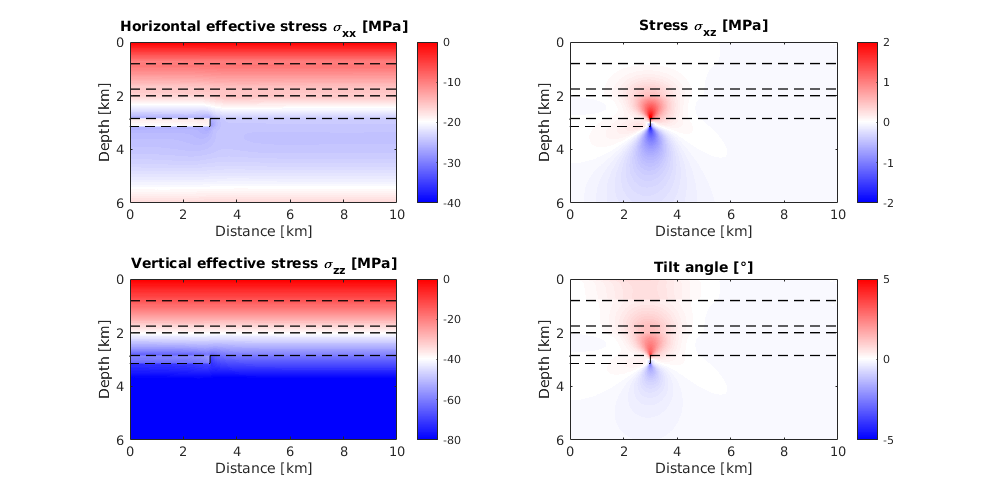

figure(1)
fig = figure('Position', [1 1 1000 500]);
subplot(2,2,1)
imagesc(G.xx/1e3, G.zz/1e3, stress.xx')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Horizontal effective stress \sigma_{xx} [MPa]')
caxis([-40 0])

subplot(2,2,2)
imagesc(G.xx/1e3, G.zz/1e3, stress.xz')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Stress \sigma_{xz} [MPa]')
caxis([-2 2])


subplot(2,2,3)
imagesc(G.xx/1e3, G.zz/1e3, stress.zz')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Vertical effective stress \sigma_{zz} [MPa]')
caxis([-80 0])

subplot(2,2,4)
imagesc(G.xx/1e3, G.zz/1e3, Theta'*180/pi)
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
caxis([-5 5])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Tilt angle [\circ]')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

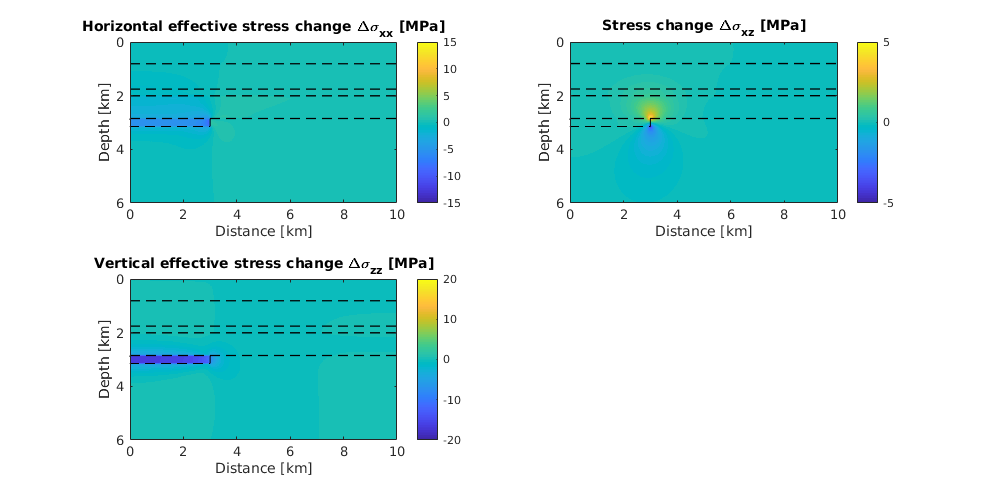


figure(2)
fig = figure('Position', [1 1 1000 500]);
subplot(2,2,1)
imagesc(G.xx/1e3, G.zz/1e3, sigma.xx')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Horizontal effective stress change \Delta\sigma_{xx} [MPa]')
caxis([-15 15])

subplot(2,2,2)
imagesc(G.xx/1e3, G.zz/1e3, sigma.xz')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Stress change \Delta\sigma_{xz} [MPa]')
caxis([-5 5])

subplot(2,2,3)
imagesc(G.xx/1e3, G.zz/1e3, sigma.zz')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '--')
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colorbar
axis('equal')
axis([0 10 0 6])
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Vertical effective stress change \Delta\sigma_{zz} [MPa]')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
caxis([-20 20])

inside_reservoir = zeros(G.nx, G.nz);
inside_reservoir(1:301, 286:316) = 1; 

Anomaly.Vp = zeros(G.nx, G.nz);
Anomaly.Vs = zeros(G.nx, G.nz);
Anomaly.del = zeros(G.nx, G.nz);
Anomaly.eps = zeros(G.nx, G.nz);
Anomaly.gam = zeros(G.nx, G.nz);


for i = 1:1:G.nx
    for j = 1:1:G.nz
        if (inside_reservoir(i,j))
            phi_c1 = 0.006;
            phi_c2 = 0.006;
            phi_c3 = 0.008;
            Fc = 3*0.037;
            F1 = 3*0.0022;
            F2 = 0;
            F3 = 3*(-0.0004);
        else
            phi_c1 = 0.006;
            phi_c2 = 0.006;
            phi_c3 = 0.008;
            Fc = 0.037;
            F1 = 0.0022;
            F2 = 0;
            F3 = -0.0004;
        end
            
        C11 = Model.Vp(i,j)^2*Model.rho(i,j)/1e9;
        C66 = Model.Vs(i,j)^2*Model.rho(i,j)/1e9;
        C12 = C11 - 2*C66; 
        
        dSx = sigma.xx(i,j);
        dSy = sigma.xx(i,j);
        dSz = sigma.zz(i,j);

        

        C0 = [C11 C12 C12 0   0   0; ...
              C12 C11 C12 0   0   0; ...
              C12 C12 C11 0   0   0; ...
              0   0   0   C66 0   0; ...
              0   0   0   0   C66 0; ...
              0   0   0   0   0   C66];
          
        S0 = inv(C0);

%         fc10 = phi_c1; 
%         fc20 = phi_c2; 
%         fc30 = phi_c3; 
%     
%         fc1 = phi_c1*exp(Fc*dSx); 
%         fc2 = phi_c2*exp(Fc*dSx); 
%         fc3 = phi_c3*exp(Fc*dSz); 
        
        % exp(-x) = 1 - x
        
        fc1 = phi_c1*Fc*dSx; 
        fc2 = phi_c2*Fc*dSy; 
        fc3 = phi_c3*Fc*dSz; 
        
    
        fs1 = S0(1,1)*dSx + S0(1,2)*dSy + S0(1,3)*dSz;
        fs2 = S0(1,2)*dSx + S0(2,2)*dSy + S0(2,3)*dSz;
        fs3 = S0(1,3)*dSx + S0(2,3)*dSy + S0(3,3)*dSz;
    
%         dSc0 = [fc10    0       0       0       0       0; ...
%                0      fc20     0       0       0       0; ...
%                0      0       fc30     0       0       0; ...
%                0      0       0       fc20+fc30 0       0; ...
%                0      0       0       0       fc10+fc30 0; ...
%                0      0       0       0       0       fc10+fc20]; 
    
        dSc = [fc1    0       0       0       0       0; ...
               0      fc2     0       0       0       0; ...
               0      0       fc3     0       0       0; ...
               0      0       0       fc2+fc3 0       0; ...
               0      0       0       0       fc1+fc3 0; ...
               0      0       0       0       0       fc1+fc2]; 
    
         dSs1 = [fs1    0       0       0       0       0; ...
                 0      fs2     0       0       0       0; ...
                 0      0       fs3     0       0       0; ...
                 0      0       0       fs2+fs3 0       0; ...
                 0      0       0       0       fs1+fs3 0; ...
                 0      0       0       0       0       fs1+fs2]; 
    
         dSs2 = [fs2+fs3 fs1+fs2 fs1+fs3 0      0       0; ...
                 fs1+fs2 fs1+fs3 fs2+fs3 0      0       0; ...
                 fs1+fs3 fs2+fs3 fs1+fs2 0      0       0; ...
                 0       0       0       2*fs1-fs2-fs3  0   0; ...
                 0       0       0       0      2*fs2-fs1-fs3    0; ...
                 0       0       0       0      0       2*fs3-fs1-fs2];
      
        dSs3 =  [0      fs3     fs2     0       0       0; ...
                 fs3    0       fs1     0       0       0; ...
                 fs2    fs1     0       0       0       0; ...
                 0      0       0      -2*fs1   0       0; ...
                 0      0       0       0      -2*fs2   0; ...
                 0      0       0       0       0      -2*fs3];
   
        %S = S0 - Fc*dSc0 + Fc*dSc + F1*dSs1 + F2*dSs2 + F3*dSs3; 
        S = S0 + Fc*dSc + F1*dSs1 + F2*dSs2 + F3*dSs3; 
        
        C = inv(S);
        
        alpha = sqrt(C(1,1)*1e9/Model.rho(i,j));
        beta  = sqrt(C(4,4)*1e9/Model.rho(i,j));
        eps = (C(1,1) - C(3,3))/(2*C(3,3));
        gam = (C(6,6) - C(4,4))/(2*C(4,4));
        del = ((C(1,3) + C(4,4))^2 - (C(3,3) - C(4,4)).^2)/(2*C(3,3)*(C(3,3) - C(4,4)));
        
        Anomaly.alpha(i,j) = alpha; 
        Anomaly.beta(i,j) = beta; 
        Anomaly.del(i,j) = eps;
        Anomaly.eps(i,j) = gam;
        Anomaly.gam(i,j) = del; 
       
    end
end       


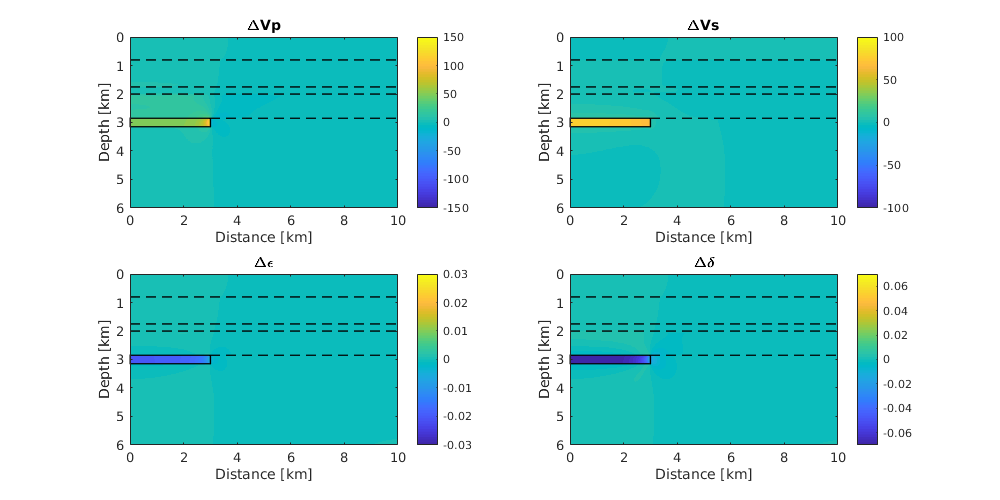

figure(433)
fig = figure('Position', [1 1 1000 500]);
subplot(2,2,1)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.alpha' - Model.Vp')
hold on
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
xlabel('Distance [km]')
ylabel('Depth [km]')
title('\DeltaVp')
caxis([-150 150])
colorbar; 
subplot(2,2,2)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.beta' - Model.Vs')
hold on
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
xlabel('Distance [km]')
ylabel('Depth [km]')
caxis([-100 100])
title('\DeltaVs')
colorbar; 
subplot(2,2,3)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.eps')
hold on
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
xlabel('Distance [km]')
ylabel('Depth [km]')
title('\Delta\epsilon')
caxis([-0.03 0.03])
colorbar; 
subplot(2,2,4)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.del')
hold on
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
xlabel('Distance [km]')
ylabel('Depth [km]')
title('\Delta\delta')
colorbar; 
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
caxis([-0.07 0.07])

## Calculate time-shifts

Gold = G.oldGrid;
% baseline
BTTI = 1000*ones(G.nx,G.nz,G.nx);
for i=1:10:G.nx
    S = [G.xx(i),0,0];
    Vp = Model.Vp; 
    %Epsilon = zeros(G.nx, G.nz);
    %Delta = zeros(G.nx, G.nz);
    %Theta = zeros(G.nx, G.nz);
    %BTTI(:,:,i) = FSM2DTTI(G, S, Vp, Epsilon, Delta, Theta);
    BTTI(:,:,i) = FSM2D(Gold, S, Vp);
end

% monitor
MTTI = 1000*ones(G.nx,G.nz,G.nx);
for i=1:10:G.nx
    S = [G.xx(i),0,0];
    Vp = Anomaly.alpha;
    %Epsilon = Anomaly.eps;
    %Delta = Anomaly.del;
    %Theta = zeros(G.nx, G.nz);
    %STTI(:,:,i) = FSM2DTTI(G, S, Vp, Epsilon, Delta, Theta);
    MTTI(:,:,i) = FSM2D(Gold, S, Vp);
end

bTTI = min(BTTI,[],3);
mTTI = min(MTTI,[],3);
dtti = mTTI - bTTI; 

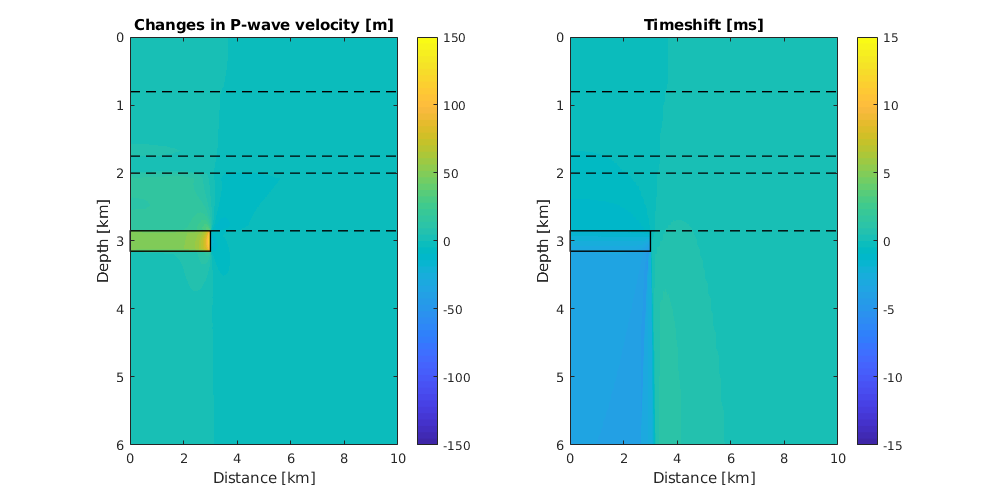

figure(4)
fig = figure('Position', [1 1 1000 500]);
subplot(1,2,1)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.alpha' - Model.Vp')
hold on 
%contour(G.xx/1e3, G.zz/1e3, Results5.disp_y(:,:,tt)'-Results5.disp_y(:,:,1)', 'ShowText', 'off', 'Color', 'white')
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
caxis([-150 150])
colorbar
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Changes in P-wave velocity [m]')

subplot(1,2,2)
imagesc(G.xx/1e3, G.zz/1e3, 2*dtti'*1e3')
hold on 
%contour(G.xx/1e3, G.zz/1e3, Results7.disp_y(:,:,tt)'-Results7.disp_y(:,:,1)', 'ShowText', 'off', 'Color', 'white')
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
caxis([-15 15])
colorbar
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Timeshift [ms]')

## R-factor

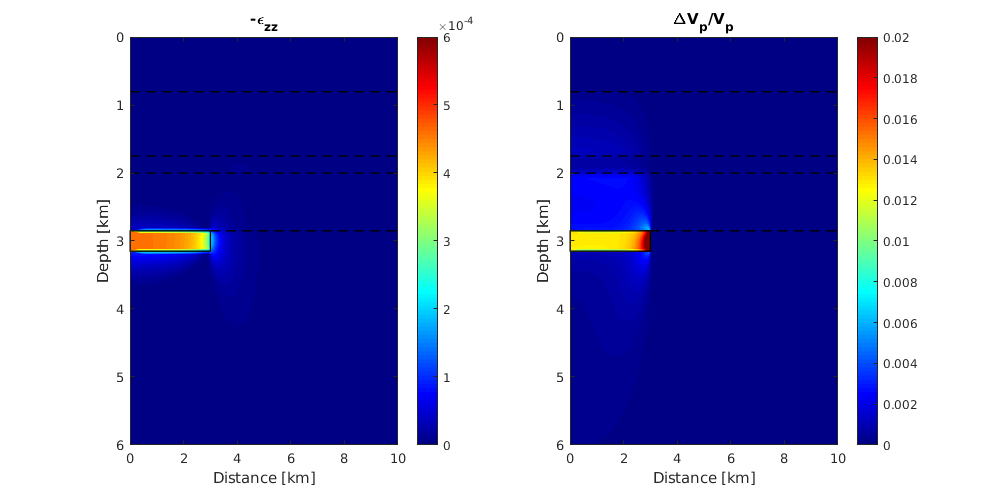

figure(4)
fig = figure('Position', [1 1 1000 500]);
subplot(1,2,1)
imagesc(G.xx/1e3, G.zz/1e3, -(Results.strain_y(:,:,tt)'-Results.strain_y(:,:,1)'))
hold on
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
caxis([-0.000 0.0006])
colorbar
xlabel('Distance [km]')
ylabel('Depth [km]')
title('-\epsilon_{zz}')

dV = (Anomaly.alpha - Model.Vp)./Model.Vp;

subplot(1,2,2)
imagesc(G.xx/1e3, G.zz/1e3, dV')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
colormap('jet')
caxis([-0.0 0.02])
colorbar
xlabel('Distance [km]')
ylabel('Depth [km]')
title('\DeltaV_p/V_p')